# Quasilinear equations of the parabolic type

## Taks 1

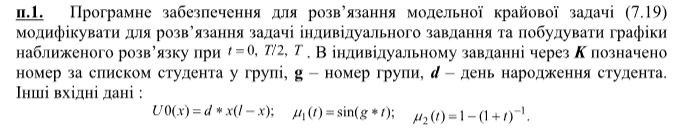

global a b 
% параметри задачі : 
a = 0; b = 1; 
% параметри різницевої схеми  та ітераційного процесу: 
N = 201; N1 = N - 1; x = linspace(a, b, N); h = x(2) - x(1); 
tau = 1e-3; M = 500; 
ep = 1e-8; smax = 1000; 
% обчислення додаткових констант : 
tau2 = 0.5 .* tau; gs = tau2 ./ (h .* h); gs2 = 2 .* gs; 
ck = 1 + gs2; ckj = 1 - gs2; 

% Розв'язування квазілінійної крайової задачі для одновимірного 
% рівняння параболічного типу різницевим методом (симетрична схема) 

% формування початкових умов при t=0 і матриці СЛАР : 
A = zeros(N, 1); B = A; C = A; F = A; fj = A; Y = A; 
for k = 1 : N 
    Y(k) = t7_u0(x(k)); A(k) = gs; B(k) = gs; 
end 

A(1) = 0; C(1) = 1; B(1) = 0; % враховуємо крайові умови при x=a 
A(N) = 0; C(N) = 1; B(N) = 0; % враховуємо крайові умови при x=b 
Y0 = Y;  % запам'ятовуємо для побудови графіку розв'язку в t=0 

for j = 1 : M 

    % знаходження наближеного розв'язку Y(:) на черговому шарі t=t(j) : 
    t = j .* tau; 

    % формування фіксованої правої частини : 
    for k = 2 : N1 
        fj(k) = gs .* (Y(k - 1) + Y(k + 1)) + ckj .* Y(k); 
    end 
    F(1) = t7_mj1(t); F(N) = t7_mj2(t); 

    % ітераційний процес на j-му шарі  : 
    Fs = 0; s = 0; Yj = Y; 
    while ~Fs & s < smax 
        Fs = 1; Ys = Y; 
    
        % формування СЛАР : 
        for k = 2 : N1 
            y = Ys(k); yy = 0.5 .* (y + Yj(k)); 
            gu = tau2 .* t7_dfu(yy); C(k) = ck - gu;  
            F(k) = fj(k) + tau .* t7_f(yy) - gu .* y; 
        end 
    
        % розв'язок СЛАР, знаходження Y(:) : 
        [Y, alfa]  =  m_progn(A, C, B, F); 
        for k = 2 : N1 
            Fs = abs(Y(k) - Ys(k))< ep; 
            if ~Fs 
                break 
            end 
        end 
    end 

    if j == 1
        Yt0 = Y;
    end
    if j == 50
        Yt1 = Y;
    end
    if j == 100
        Yt2 = Y;
    end
    if j == 300
        Yt3 = Y;
    end

    if j * 2 == M 
        Y1 = Y; %запам'ятовуємо для побудови графіку розв'язку в t=M*tau/2 
    end 
end 

**В t=0 графік надто сильно відрізняється, модифікуємо трохи метод щоб подивитися дільше розв'язків**

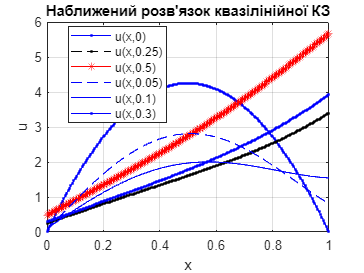

% побудова графіків розв'язку при t=0, M*tau/2, M*tau : 
t = M .* tau; t1 = t ./ 2; T1 = num2str(t1); T = num2str(t); 
plot(x, Y0, 'b.-', x, Y1, 'k.--', x, Y, 'r*-') 
title('Наближений розв''язок квазілінійної КЗ') 
xlabel('x'), ylabel('u'), grid on; 

hold on;

h = plot(x, Yt1, 'b--', x, Yt2, 'b*-', x, Yt3, 'b.-');
T11 = num2str(50 .* tau); T12 = num2str(100 .* tau); T13 = num2str(300 .* tau);
legend('u(x,0)',strcat('u(x,',T1,')'),strcat('u(x,',T,')'), strcat('u(x,',T11,')'),strcat('u(x,',T12,')'),strcat('u(x,',T13,')'), 'Location','Best');
set(h(1),'linewidth', 0.1);
set(h(2),'linewidth', 0.1);
set(h(3),'linewidth', 0.1);

hold off;

function f = t7_f(u) 
    % функція f(u) 
    f = u + cos(u); 
end 

function f = t7_dfu(u) 
    % Похідна від функції f(u) по u 
    f = 1 - sin(u); 
end 

function mj = t7_mj1(t) 
    % функція  мю1(t) 
    mj = sin(t); 
end 

function mj = t7_mj2(t) 
    % функція  мю2(t) 
    mj = 17 - 17 ./ (1 + t); 
end 

function u = t7_u0(x) 
    % функція   u0(x) 
    u = 17 .* x * (1 - x); 
end 

function [y, alfa]  =  m_progn(a, c, b, f)  
    n = length(c); n1 = n - 1; 
    % пряма прогонка: 
    alfa = zeros(1, n); y = alfa; 
    beta = alfa; ka = ones(1, n); te = alfa; 
    C = c(1); A = a(2); F = f(1); Q = f(2); 
    for k = 1 : n1 
        j = k + 1; 
        if abs(C) >= abs(b(k)) 
            alfa(j) = b(k) ./ C; beta(j) = F ./ C; 
            C = c(j) - A .* alfa(j); F = Q + A .* beta(j); 
            te(j) = ka(k); ka(j) = j; 
            if k ~= n1 
                j = j + 1; A = a(j); Q = f(j); 
            end 
        else 
            alfa(j) = C ./ b(k); beta(j) = -F ./ b(k); 
            C = c(j) .* alfa(j) - A; F = Q - c(j) .* beta(j); 
            te(j) = j; ka(j) = ka(k); 
            if k ~= n1 
                j1 = j; j = j + 1; 
                A = a(j) .* alfa(j1); Q = f(j) + a(j) .* beta(j1); 
            end 
        end   
    end 
    % зворотня прогонка: 
    y(ka(n)) =F ./ C; 
    for k=n1 : -1 : 1 
        j = k + 1; y(te(j)) = alfa(j) .* y(ka(j)) + beta(j); 
    end 
end 